boat.L = 0.4;         % length in meters
boat.W = 0.2;         % width in meters
boat.HB = boat.W / 2;  % half breadth in meters
boat.D = 0.1;         % depth in meters

%boat.mass = 18;       % kg
boat.n = 2;         % shape parameter (dimensionless)
boat.density = 50; %kg/m^3

water_density = 1000; %kg/m^3
colormap;
clear mesh;

mesh.dy = 0.001;
mesh.dz = 0.001;
mesh.dx = 0.001;
mesh.ys = -boat.HB:mesh.dy:boat.HB;
mesh.zs = 0:mesh.dz:boat.D;
mesh.xs = -boat.L/2:mesh.dx:boat.L/2;
[mesh.xgrid, mesh.ygrid,mesh.zgrid] = meshgrid(mesh.xs, mesh.ys, mesh.zs);
[mesh.xgrid, mesh.ygrid] = meshgrid(mesh.xs, mesh.ys);

hull3D = computeHull3D(mesh,boat);
clear position
position.x=0;
position.y=0;
position.z=0.02;

boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.mass/boat.num_cells;
boiyant = boat.mass*9.81;

theta = 1;
sum(masses3D(:))

ans = 1.2015

masses3D = hull3D*boat.mass_per_cell;
masses3D=addMass3(1.00,position,masses3D,mesh) 

masses3D = 
(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

boat.COM = centerOfMass3D(masses3D, mesh)

boat = struct with fields:
                L: 0.4000
                W: 0.2000
               HB: 0.1000
                D: 0.1000
                n: 2
          density: 50
        num_cells: 4029122
             mass: 0.2015
    mass_per_cell: 5.0000e-08
              COM: [-0.0832 0.0832 0.0274]


sum(masses3D(:))

ans = 1.2015

fun = @(d) massDiff3D(mesh, boat, theta, d);
d0 = boat.D/2;
d = fzero(fun, d0);
water = computeWater3D(d, theta, mesh);
sub_region = hull3D & water;
COB = centerOfMass3D(sub_region, mesh)

COB =     0.0000    0.0008    0.0116


force = [0, -boiyant*sind(theta), boiyant*cosd(theta)]

force =          0   -0.0345    1.9760


r = COB - boat.COM

r =     0.0832   -0.0824   -0.0158


moment = cross(r, force)

moment =    -0.1633   -0.1645   -0.0029


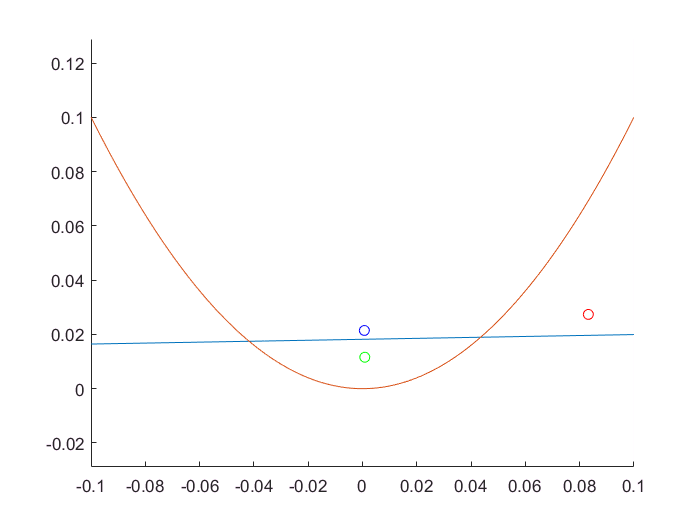

Y = -0.1:0.001:0.1;
station = (((2.*Y)./boat.W).^2).*boat.D;
waterline = tand(theta).*Y + d;
figure;
hold on;
plot(force(2)/(200) + COB(2), force(3)/(200) + COB(3), 'bo');
plot(COB(2), COB(3), 'go');
plot(boat.COM(2), boat.COM(3), 'ro');
plot(Y,waterline);
plot(Y,station);
xlim([-0.1,0.1]);
axis('equal');
hold off;


hull3D = computeHull3D(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.mass/boat.num_cells;

masses3D = hull3D*boat.mass_per_cell;

boat.COM = centerOfMass3D(masses3D, mesh);

figure;
hold on;
plot(Y,station);
torques = [];

plot(boat.COM(2), boat.COM(3), 'ro');
for theta = 0:5:160
    clear r
    fun = @(d) massDiff3D(mesh, boat, theta, d);
    d0 = boat.D/2;
    d = fzero(fun, d0);
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    COB = centerOfMass3D(sub_region, mesh); %find COB
    plot(COB(2), COB(3), 'go');
    
    r = COB - boat.COM;
    boiyant = boat.mass*9.81;
    force = [0, -boiyant*sind(theta), boiyant*cosd(theta)];
    moment = cross(r,force);
    
   
   
    torques = [torques; moment];
  
end

Exiting fzero: aborting search for an interval containing a sign change
    because no sign change is detected during search.
Function may not have a root.


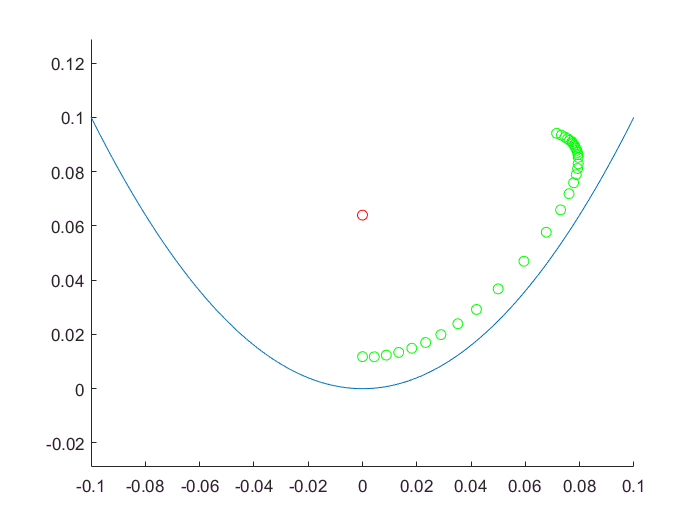

axis('equal');
hold off;

% [X,Y,Z] = ndgrid(1:size(sub_region,1), 1:size(sub_region,2), 1:size(sub_region,3));
% pointsize = 30;
% scatter3(X(:), Y(:), Z(:), pointsize, sub_region(:));
% axis('equal');

torques

torques =    -0.0000    0.0000         0
   -0.0004    0.0000    0.0000
   -0.0006    0.0000    0.0000
   -0.0004    0.0000    0.0000
    0.0006    0.0000    0.0000
    0.0025    0.0000    0.0000
    0.0059    0.0000    0.0000
    0.0114    0.0000    0.0000
    0.0194    0.0000    0.0000
    0.0319    0.0000    0.0000


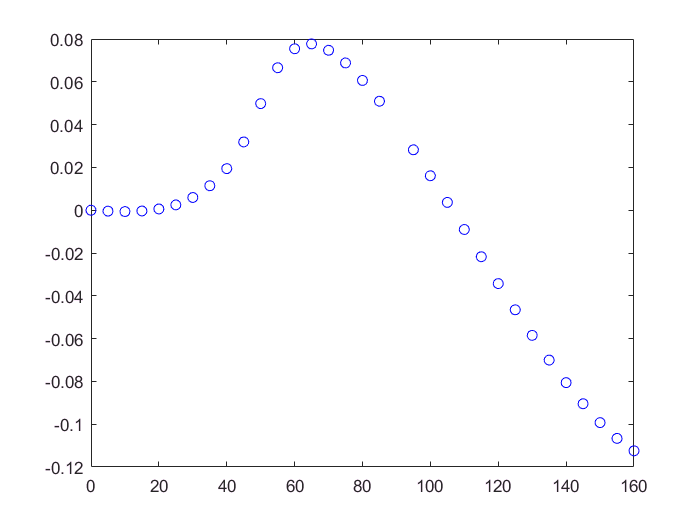

figure;
thetas = 0:5:160;
plot(thetas,torques(:,1), 'bo');

torques(:,1)

ans =    -0.0000
   -0.0004
   -0.0006
   -0.0004
    0.0006
    0.0025
    0.0059
    0.0114
    0.0194
    0.0319


function COM = centerOfMass3D(masses, mesh)
    M = sum(masses(:));
    x_masses = masses.*mesh.xgrid;
    x_COM = sum(x_masses(:))/M;
    y_masses = masses.*mesh.ygrid;
    y_COM = sum(y_masses(:))/M;
    
    z_masses = masses.*mesh.zgrid;
    z_COM = sum(z_masses(:))/M;
    COM = [x_COM,y_COM, z_COM];
end




function water = computeWater3D(d,theta,mesh)
    % water: compute the level of the water
    % d: depth of waterline in meters
    % theta: angle of waterline in degrees
    % mesh: structure containing ys and zgrid
    % returns: logical matrix
    
    y = mesh.ygrid;
    
    z = tand(theta) .* y + d;
    if theta <= 90
        water = mesh.zgrid <z;
    end
    if theta > 90
        water = mesh.zgrid > z;
    end
end


function hull = computeHull3D(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    B = boat.W;
    D = boat.D;
    L = boat.L;
    center_station = (((2.*mesh.ygrid)./B).^2).*D;
    profile = (((2.*mesh.xgrid)./L).^4).*D;
    z = center_station + profile;
    hull = mesh.zgrid  >z;
end



function diff = massDiff3D(mesh,boat,theta,d)
    
%     for a value of theta and d, finds the differnce 
%     in boiyant and weight forces
    
    hull3D = computeHull3D(mesh, boat);
    boat.num_cells = sum(hull3D(:));
    boat.mass = boat.num_cells*mesh.dy*mesh.dz*mesh.dx*boat.density;
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    
    displaced_water = sum(sub_region(:))*mesh.dx*mesh.dy*mesh.dz*1000;
    
    diff = boat.mass - displaced_water;
end

function hull = squareHull(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    z = 0;
    hull = mesh.zgrid  >= z;
end
function masses3D = addMass3(mass,position,masses3D,mesh) 

    ix = closestIndex(position.x,mesh.xs);
    iy = closestIndex(position.y, mesh.ys);
    iz= closestIndex(position.z,mesh.zs);
    
    
    % update the matrix
    masses3D(ix, iy,iz) = masses3D(ix, iy, iz) + mass;
end

function index = closestIndex(coord,grid)
    % closestIndex: finds the index of the grid point closest to coord
    % coord: scalar coordinate
    % grid: matrix of coordinates
    % returns: integer index
    
    % see: https://www.mathworks.com/matlabcentral/answers/152301-find-closest-value-in-array
    [c index] = min(abs(coord-grid));
end